# 测试

clc
clear
close all
addpath("src\");

## C-W交会

n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [2200., 8000., 100., 0., 0., 0.]';  % m, m/s
xf = zeros(6, 1);
step = 1;

### 双脉冲

[dv, dv0, ~] = Cw2Impulse(n, x0, tf, xf)

dv =     7.6600    4.9969    2.6630


dv0 =     1.4451
   -4.7827
    0.0842


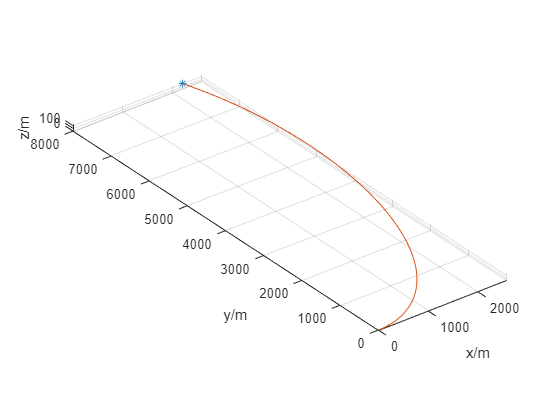

args.n = n;
r = x0(1 : 3);
v = x0(4 : 6) + dv0;
[t, x] = ode45(@(t, x) CwEq(t, x, zeros(3, 1), args), 0 : step : tf, [r; v]);
figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

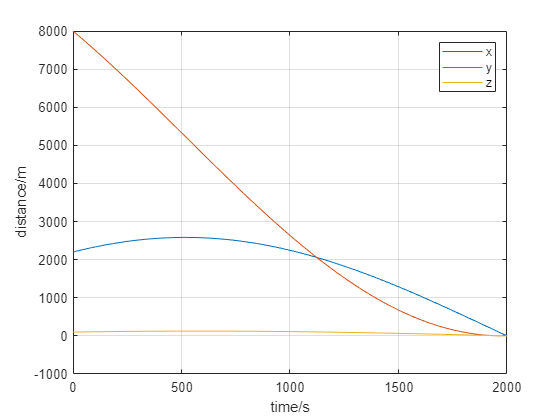

figure
plot(t, x(:, 1 : 3))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')

### 多脉冲转连续推力

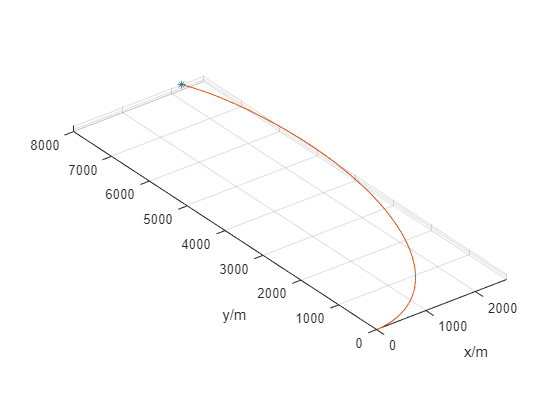

dt = 100;
args.n = n;
t1 = 0;
t2 = tf;
x1 = x0;
x2 = xf;
s0 = [];
sf = [];
for i = 1 : tf / dt / 2
    [~, dv0, dvf] = Cw2Impulse(n, x1, t2(end) - t1(end), x2);
    u0 = dv0 / dt;
    uf = dvf / dt;
    [t1, s1] = ode45(@(t, x) CwEq(t, x, u0, args), t1(end) + (0 : step : dt), x1);
%     plot(t1, s1(:, 1), 'b', t1, s1(:, 2), 'r', t1, s1(:, 3), 'y')
    [t2, s2] = ode45(@(t, x) CwEq(t, x, uf, args), t2(end) - (0 : step : dt), x2);
%     plot(t2, s2(:, 1), 'b', t2, s2(:, 2), 'r', t2, s2(:, 3), 'y')
    x1 = s1(end, :)';
    x2 = s2(end, :)';
    s0 = [s0(1 : end - 1, :); t1, s1, [u0', norm(u0)] .* ones(length(t1), 1)];
    sf = [sf(1 : end - 1, :); t2, s2, [uf', norm(uf)] .* ones(length(t2), 1)];
end
s0 = [s0; flip(sf(1 : end - 1, :))];
figure
plot3(s0(1, 2), s0(1, 3), s0(1, 4), '*')
hold on
plot3(s0(:, 2), s0(:, 3), s0(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

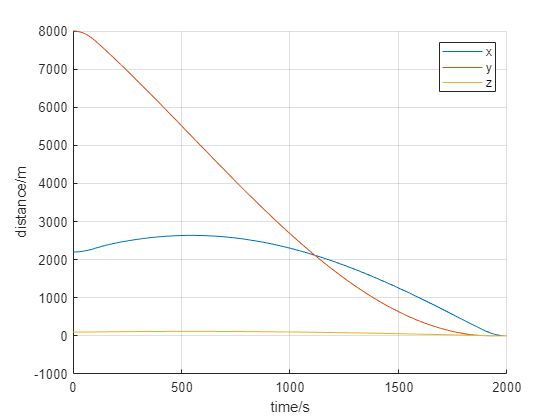

figure
hold on
plot(s0(:, 1), s0(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

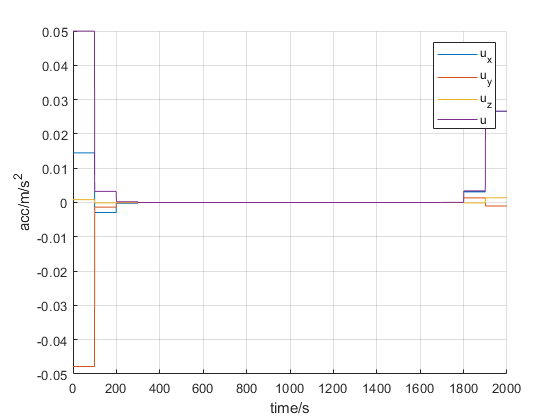

figure
hold on
plot(s0(:, 1), s0(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 高斯伪谱法

args.n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [2200., 8000., 100., 0., 0., 0.]';  % m, m/s
xf = zeros(6, 1);
lb = [-1000, -1000, -100, -10, -10, -1, -0.5, -0.5, -0.1, 0.1 * tf];
ub = [3000, 9000, 200, 10, 10, 1, 0.5, 0.5, 0.1, 1.2 * tf];

#### 时间最优

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      92    2.000000e+03    3.485e+02    9.996e-01
    1     184    1.999046e+03    1.854e-01    9.997e-01    9.121e+00
    2     276    1.998037e+03    2.039e-03    9.997e-01    1.009e+00
    3     368    1.992990e+03    5.104e-02    9.997e-01    5.047e+00
    4     460    1.967757e+03    1.283e+00    9.997e-01    2.523e+01
    5     552    1.841607e+03    3.296e+01    9.995e-01    1.262e+02
    6     645    1.212849e+03    3.185e+02    9.706e-01    6.288e+02
    7     737    1.128306e+03    3.456e+02    9.685e-01    8.456e+01
    8     829    1.128867e+03    3.390e+02    7.939e-01    5.623e-01
    9     921    1.176340e+03    8.780e-01    1.389e+00    4.751e+01
   10    1013    1.171842e+03    1.394e-01    9.608e-01    5.620e+00
   11    1105    1.159013e+03    1.230e+00    7.982e-01    1.604e+01
   12    1197    1.160329e+03    1.647e-02    5

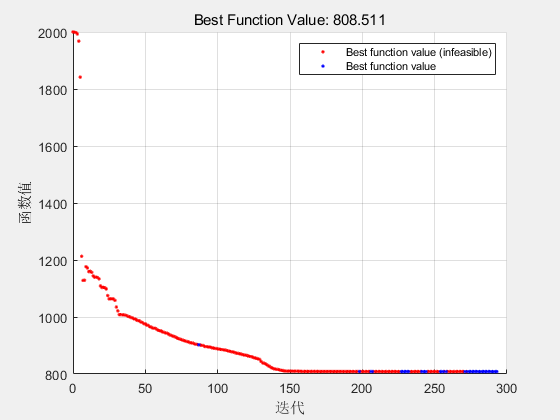


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[s, x_nlp, fval, exitflag, output, lambda, ct] = Gpm(x0, xf, @CostTime, @CwEq, s0, lb, ub, 10, step, args);

ct

ct = 53.5898

tf_ = s(end, 1)

tf_ = 808

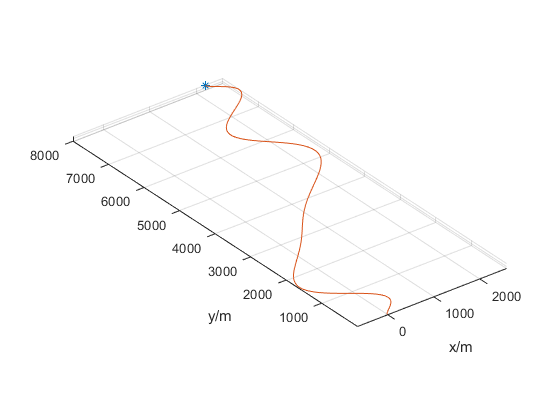

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

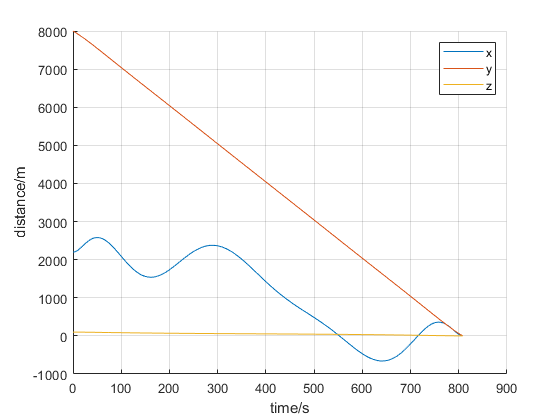

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

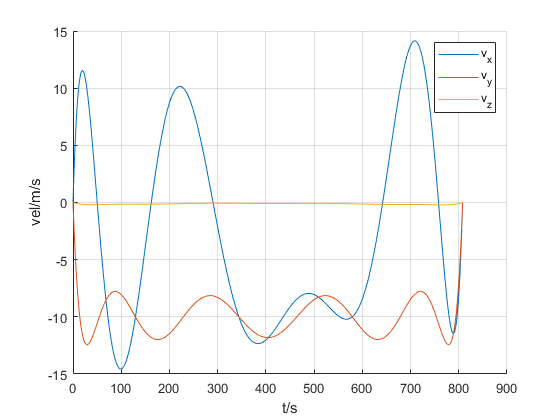

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

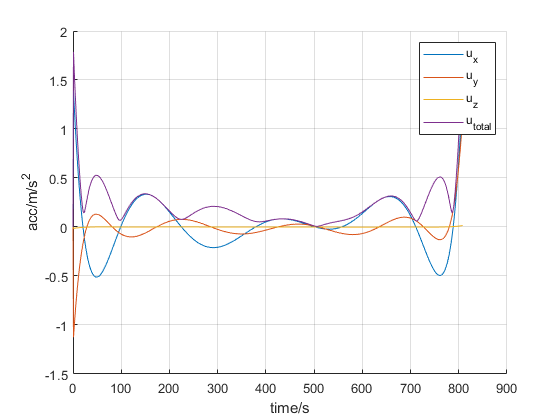

figure
hold on
plot(s(:, 1), s(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

#### 燃料最优(伪，与间接法作对比)

@CostFuel: $\int \sqrt{u_x^2 + u_y^2 + u_z^2} \mathrm{d}t$

@CostFuel2: $\frac{1}{2} \int u_x^2 + u_y^2 + u_z^2 \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      91    1.103463e-01    3.485e+02    6.236e-04
    1     182    1.459889e-01    1.556e-03    1.336e+00    9.066e+00
    2     273    1.459887e-01    5.362e-09    1.000e-01    1.803e-03
    3     364    1.459882e-01    1.188e-07    1.000e-03    1.075e-03
    4     455    1.459858e-01    5.587e-07    4.676e-04    5.209e-03
    5     546    1.459742e-01    1.990e-06    4.675e-04    2.604e-02
    6     637    1.459158e-01    1.498e-05    4.665e-04    1.301e-01
    7     728    1.456281e-01    7.065e-05    4.631e-04    6.484e-01
    8     819    1.442852e-01    2.695e-04    4.437e-04    3.187e+00
    9     910    1.396505e-01    1.702e-03    3.206e-04    1.459e+01
   10    1001    1.373305e-01    1.107e-04    5.499e-04    1.995e+01
   11    1092    1.373301e-01    2.277e-08    2.223e-04    3.193e-03
   12    1183    1.373279e-01    3.698e-08    2

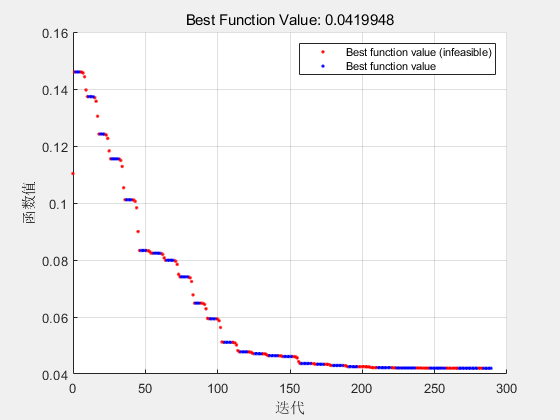


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


args.n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [2200., 8000., 100., 0., 0., 0.]';  % m, m/s
xf = zeros(6, 1);
lb = [-1000, -1000, -100, -10, -10, -1, -0.5, -0.5, -0.1];
ub = [3000, 9000, 200, 10, 10, 1, 0.5, 0.5, 0.1];
[s, x_nlp, fval, exitflag, output, lambda, ct] = Gpm2(x0, xf, @CostFuel2, @CwEq, s0, lb, ub, 10, step, args);

ct

ct = 89.6551

tf_ = s(end, 1)

tf_ = 2000

J = CostFuel(s, tf_)

J = 11.3212

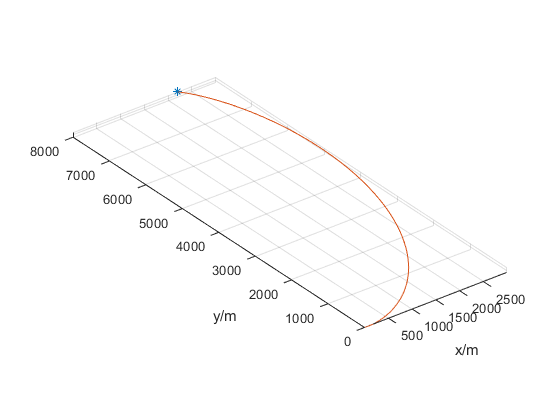

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

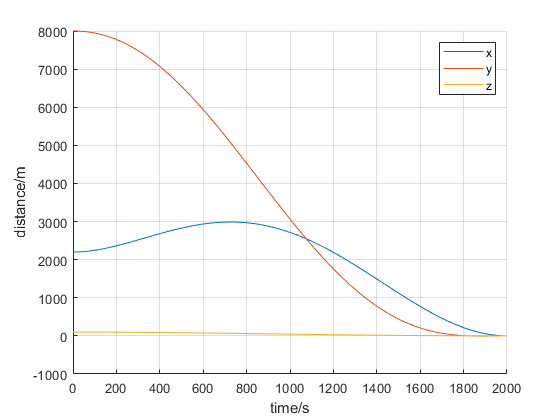

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

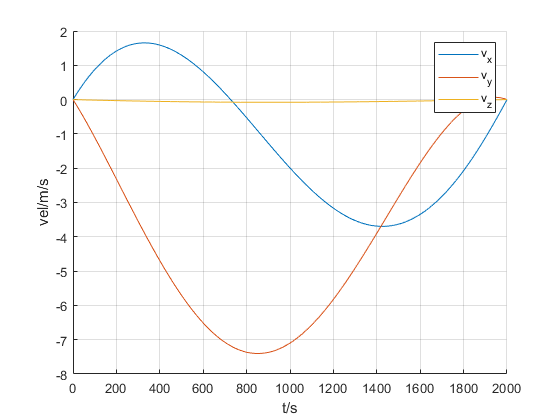

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

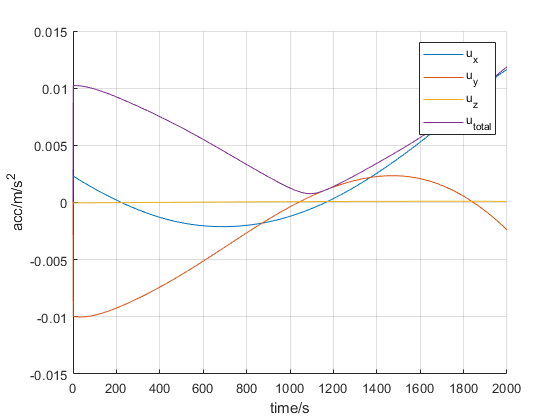

figure
hold on
plot(s(:, 1), s(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

#### 燃料最优(真)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      91    7.384547e+00    3.485e+02    2.426e-02
    1     182    8.871438e+00    1.549e-03    1.260e+02    9.066e+00
    2     273    8.860031e+00    2.037e-05    2.176e+00    1.072e-01
    3     364    8.805499e+00    1.748e-04    3.209e+00    5.294e-01
    4     455    8.612456e+00    9.869e-04    6.982e+01    2.499e+00
    5     547    8.601593e+00    8.768e-04    1.097e+02    8.883e-01
    6     638    8.598032e+00    1.151e-04    1.715e+01    2.591e-01
    7     729    8.596543e+00    2.089e-05    9.553e+00    7.060e-02
    8     820    8.587431e+00    6.042e-05    4.481e+01    3.888e-01
    9     911    8.569409e+00    2.800e-05    9.946e+01    9.396e-01
   10    1002    8.541810e+00    1.190e-04    1.096e+02    1.818e+00
   11    1093    8.528341e+00    1.511e-04    1.060e+02    1.453e+00
   12    1184    8.522049e+00    1.091e-04    5

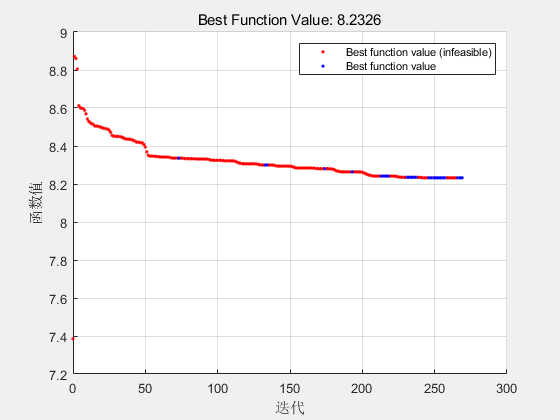


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[s, x_nlp, fval, exitflag, output, lambda, ct] = Gpm2(x0, xf, @CostFuel, @CwEq, s0, lb, ub, 10, step, args);

ct

ct = 87.4147

tf_ = s(end, 1)

tf_ = 2000

J = CostFuel(s, tf_)

J = 8.2326

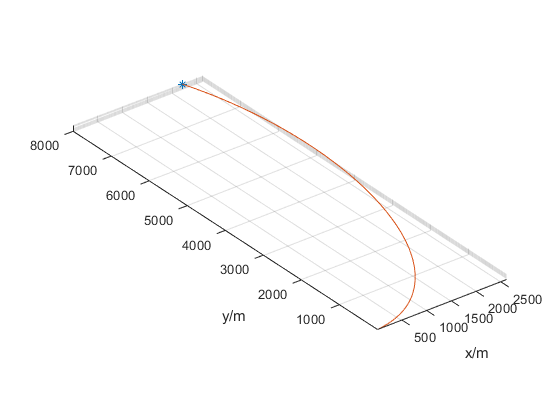

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

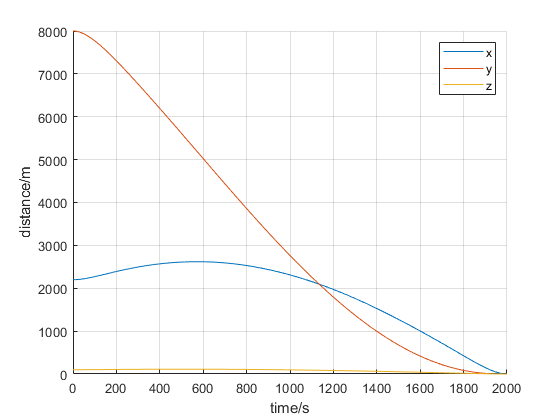

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

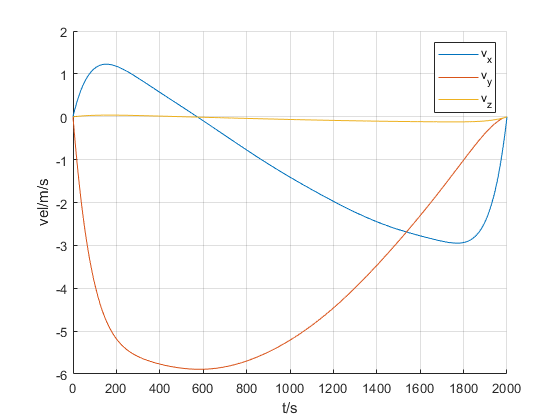

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

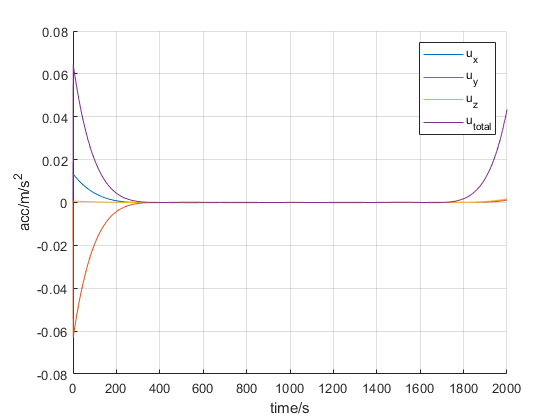

figure
hold on
plot(s(:, 1), s(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

## 连续推力

### 间接法

tic
% [t, x] = CwIndirOpt(x0, n, tf, step, 'Riccati');
[t, x] = CwIndirOpt(x0, n, tf, step);
toc

历时 0.066870 秒。


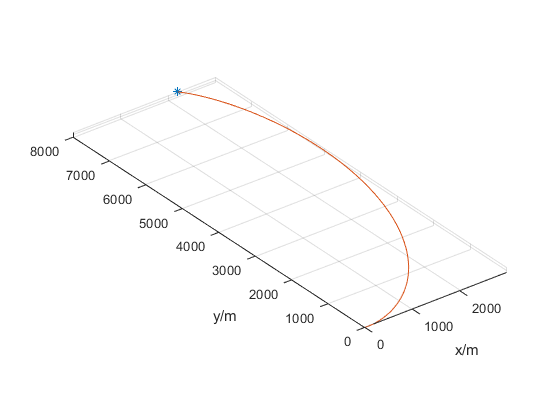

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

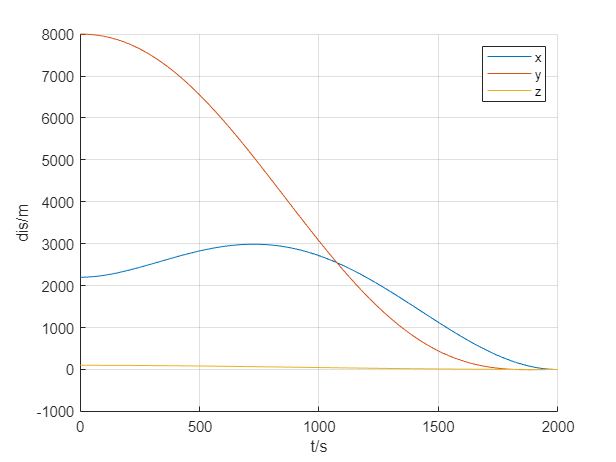

figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off

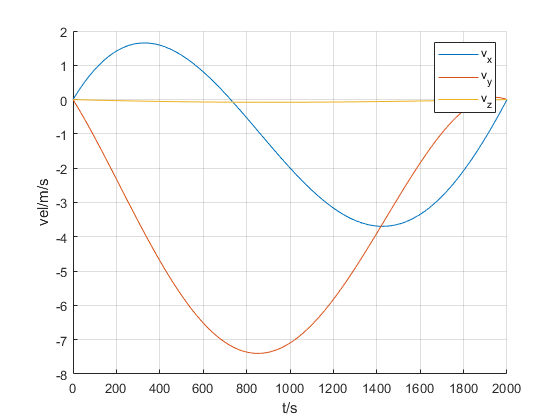

figure
hold on
plot(t, x(:, 4))
plot(t, x(:, 5))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

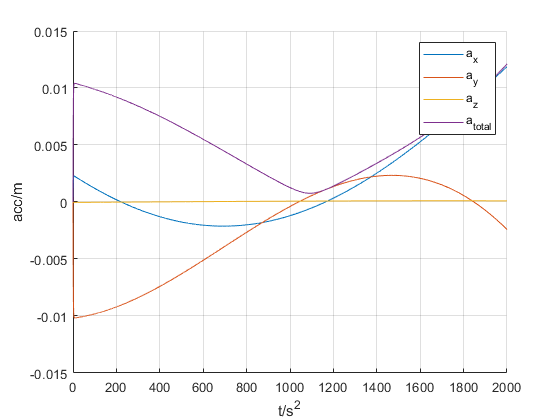

figure
hold on
plot(t, x(:, 7))
plot(t, x(:, 8))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off

sum(a) / length(t) * tf

ans = 11.3030

## 固定推力

x0 = [-2200., -8000., 100., 0., 0., 0.]';  % m, m/s
tf = 2000.; % s
n = 0.00111; % rad/s
tspan = 1;
f = 0.02; % m/s^2

### 间接法

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    3.598836e+01     1.839e+04     1.000e+00     0.000e+00     1.416e-04  
    1          16    3.598836e+01     2.462e+04     1.000e+00     2.120e+00     2.853e+07  
    2          35    3.598836e+01     2.444e+04     1.977e-02     6.483e-02     2.853e+07  
    3          49    3.598836e+01     2.267e+04     1.176e-01     4.960e-01     2.853e+07  
    4          57    1.486835e+01     1.006e+04     1.000e+00     1.055e+03     2.853e+07  
    5          65    1.946836e+01     3.188e+03     1.000e+00     2.293e+02     2.853e+07  
    6          76    1.414836e+01     2.543e+03     3.430e-01     2.655e+02     2.853e+07  
    7         104    1.414836e+01     2.543e+03     7.979e-04     4.058e-01     2.853e+07  
    8         116    2.034836e+01     1.720e+03     2.401e-01     3.102e+02     2.

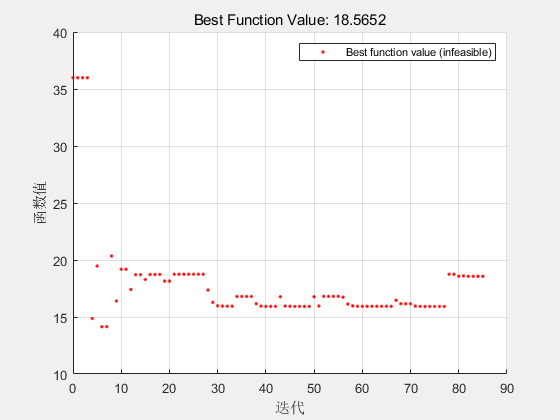


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     5.9332
   -0.1031
   -0.1047
    0.4941
   -0.0155
   -0.7943
  940.5275


fval = 18.5652

exitflag = -2

output = 包含以下字段的 struct :
         iterations: 85
          funcCount: 2993
          algorithm: 'sqp'
            message: '↵Converged to an infeasible point.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance but constraints are not↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-09, but the relative maximum constraint↵violation, 7.069521e-03, exceeds options.ConstraintTolerance = 1.000000e-07.↵↵'
    constrviolation: 129.9916
           stepsize: 1.0929e-09
       lssteplength: 7.2575e-10
      firstorderopt: 2.8533e+07
       bestfeasible: []


tic
[t, x] = CwIndirOpt3(x0, n, f, tf, tspan);

toc

历时 47.797388 秒。


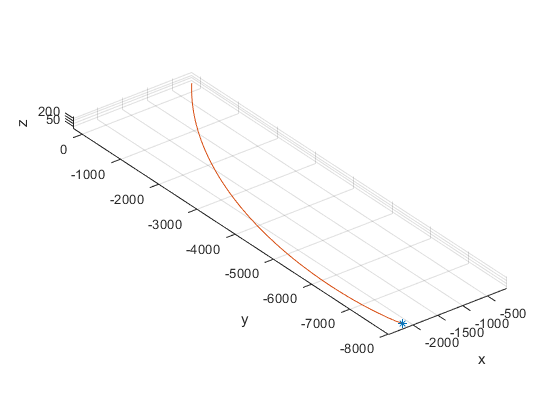

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on

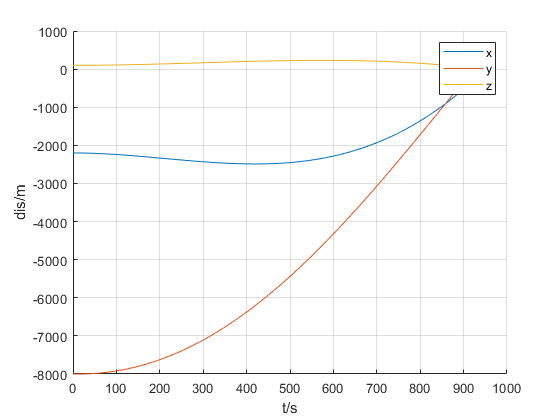

figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off

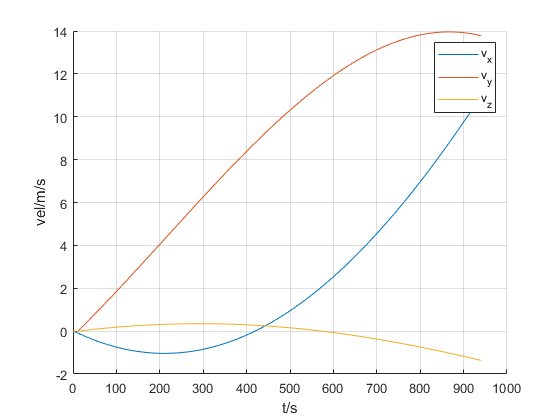

figure
hold on
plot(t, x(:, 4))
plot(t, x(:, 5))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

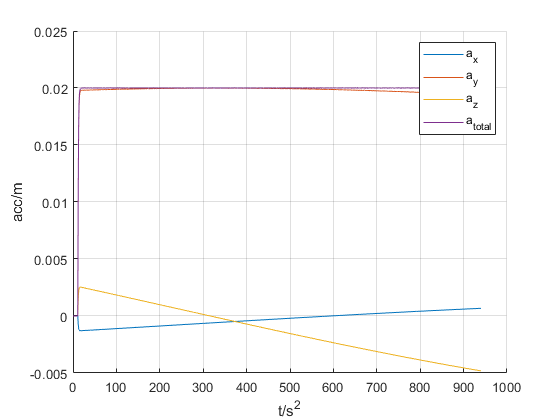

figure
hold on
plot(t, x(:, 7))
plot(t, x(:, 8))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off

sum(a) / length(t) * tf

ans = 39.4585